# Algoritmos Numéricos por Computadora

# Examen Final - Otoño 2019

**Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).**

**Sube tu archivo resultado a comunidad **$\to$** Examen Final antes de las 2pm.**

**Al correr tu script deben desplegarse los resultados.**

**1a.** Escribe, al final del script, la función * jacobiana(f,x)* que calcula numéricamente la matriz jacobiana de la función vectorial $f$ en el vector $x$.

**1b. **Escribe, al final del script, el método de *Newton-Raphson *de varias variables modificado para que no reciba la matriz jacobiana sino que la calcule en cada iteración utilizando la función del problema 1. *NewtonRaphsonVV(f,x)*

**2. **Utiliza el (nuevo) método de Newton-Raphson de varias variables para determinar puntos de intersección entre la circunferencia $x^2 +y^2 =3$ y la hipérbola $\textrm{xy}=1$.

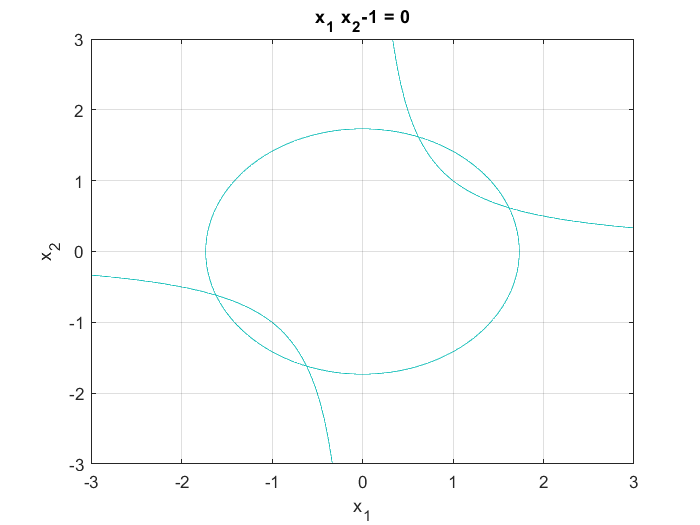

f1 = @(x1,x2) x1.^2 + x2.^2 -3;
f2 = @(x1,x2) x1.*x2 -1;
ezplot(f1,[-3,3])
grid on
hold on
ezplot(f2,[-3,3])
hold off


%Estamos buscando 4 puntos entonces debemos correr NewtonRaphsonVV 4 veces
%en diferentes regiones. Iremos de izquierda a derecha.
a = -2;
b = -1;

x01 = [a ; b];
[x1,i1] = NewtonRaphsonVV(f,x01) %Mi función NewtonRaphsonVV calcula el jacobiano

x1 =    -1.6180
   -0.6180


i1 = 6


x02 = [b ; a];
[x2,i2] = NewtonRaphsonVV(f,x02)

x2 =    -0.6180
   -1.6180


i2 = 6


x03 = -x02;
[x3,i3] = NewtonRaphsonVV(f,x03)

x3 =     0.6180
    1.6180


i3 = 6


x04 = -x01;
[x4,i4] = NewtonRaphsonVV(f,x04)

x4 =     1.6180
    0.6180


i4 = 6

**3.** Usando uno de los métodos vistos en clase para encontrar raíces de ecuaciones, calcula  una aproximación a $\sqrt[3]{25}\ldotp$

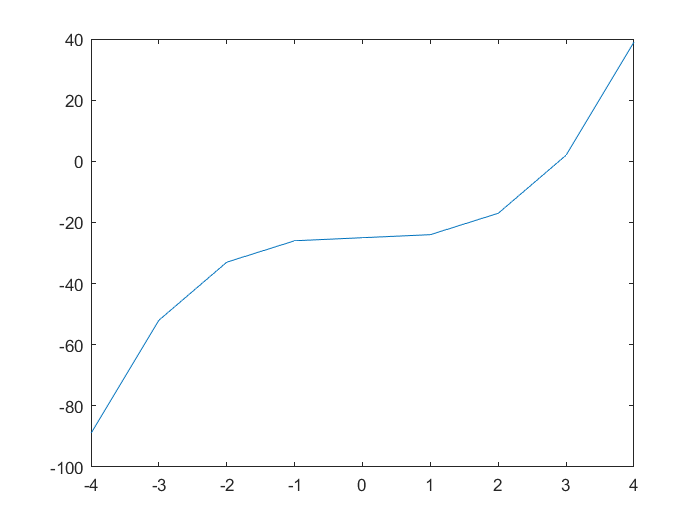

f = @(x) x.^3 - 25;
x = -4:1:4;
plot(x,f(x))

[x,i] = newtonRaphson(f,1,3);
x^3

ans = 25

**4.** Para simular el crecimiento de una población se utiliza el modelo logístico:


$$\frac{\mathrm{d}}{\mathrm{d}t}p=k_{\textrm{gm}} \left(1-\frac{p}{p_{\max } }\right)p$$


donde $p$ es la población, $k_{\textrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y $p_{\max }$ es la capacidad de carga. Simula la población mundial entre 1950 y 2020. Para la simulación utiliza las siguientes condiciones iniciales y valores de parametros: 

$p_0$ (en 1950) = 2,555 millones de personas, $k_{\textrm{gm}} =0\ldotp 026$/año y $p_{\max }$= 12,000 millones de personas.

En la simulación, usa los métodos de Euler y RK4 (con la misma h) para encontrar ¿cuántos millones de personas habrá en 2020? 

¿Por qué los resultados son diferentes al usar los dos métodos? ¿Cuál crees que es más exacto? ¿Por qué?

**5.** Si se drena el agua desde un tanque cilíndrico vertical abriendo una válvula en la base, el liquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$\frac{\mathrm{d}}{\mathrm{d}t}y=-k\sqrt{y}$               ($y$ es el nivel del agua en metros y $t$ es el tiempo en minutos)

donde $k$ es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero. 

¿En cuántos minutos se vacía un tanque si el nivel inicial del agua en el tanque es de 3m y $k=0\ldotp 06$?

f = @(t,y) -k*sqrt(y);
y0 = 3; %nivel ini
k = 0.06;
[t,y] = odeRK4(f,y0,0,55,1)
plot(t,y)


**6. ** Explica por qué el siguiente programa imprime 'Suma incorrecta'

num2hex(0.1)
suma = 0;
for i=1:10
    suma = suma + 0.1;

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


y =     3.0000    2.8970    2.7958    2.6963    2.5987    2.5029    2.4089    2.3166    2.2262    2.1376    2.0508    1.9657    1.8825    1.8011    1.7215    1.6437    1.5676    1.4934    1.4210    1.3504    1.2815    1.2145    1.1493    1.0859    1.0242    0.9644    0.9064    0.8502    0.7958    0.7431    0.6923    0.6433    0.5961    0.5506    0.5070    0.4652    0.4252    0.3869    0.3505    0.3159    0.2831    0.2521    0.2228    0.1954    0.1698    0.1460    0.1239    0.1037    0.0853    0.0687


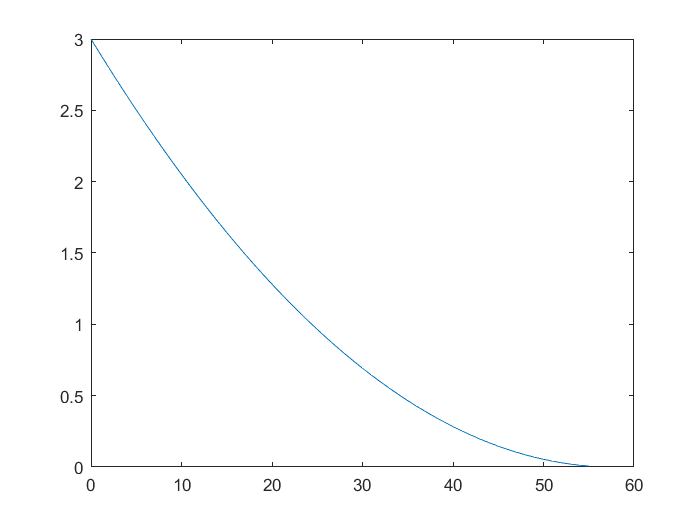

end

if (suma == 1)
    disp('Suma correcta')
else
    disp('Suma incorrecta')

ans = '3fb999999999999a'

end

**7.** A partir de la matriz X=rand(5), determina de la manera más compacta posible cuántos elementos son mayores a 0.5. Después, resta 0.5 a todos los valores que son mayores a  0.5 e imprime la matriz resultante. Cuenta cuántos elementos de esta matriz son mayores que 0.5 (la respuesta debe ser 0).

X = rand(5);
elems_mayores = length(find(X>0.5))
[r,c] = find(X>0.5);
X(sub2ind(size(X),r,c)) = X(sub2ind(size(X),r,c))-0.5
elems_mayores = length(find(X>0.5))

Suma incorrecta


## Escribe aquí la respuesta a la pregunta 1a    

function J = jacobiana(f, x)
[m,n] = size(x);

elems_mayores = 14

xs = sym('x',[1 m]);
fx = f(xs);

X =     0.1210    0.2378    0.3589    0.1339    0.3329
    0.0737    0.0634    0.2856    0.0309    0.4671
    0.0521    0.3604    0.0134    0.4391    0.1482
    0.4312    0.4344    0.1776    0.3013    0.0252
    0.2287    0.4844    0.3986    0.2955    0.3422


Js= jacobian(fx,xs);

elems_mayores = 0

J  = double(subs(Js,xs,x'));
end

## Escribe aquí la respuesta a la pregunta 1b

function [x,i] = NewtonRaphsonVV(f,x0)

x = x0;
max_iters = 1000;
tol  = eps;
condicion = true;
i = 0;
while condicion
    xp = x;
    J  = jacobiana(f,xp);
    x = xp - J\f(xp);
    i = i+1;
    condicion = norm((x-xp)./x) > tol && i<max_iters;
end
end


## Escribe aquí otras funciones que utilices